# Run Simulation

To execute a simulation you must a visualizer 2D object which allow us to visualize  pose robot and some other objects such as map, markers and waypoints.

viz = Visualizer2D;

Define an initial pose and  a differential robot.

initPose = [ 0; 0; 0.73]; % [x ; y ; theta]    

R = 0.1; 
L = 0.5; 
mobileRobot = DifferentialDrive(R,L);

Visualizer2D has some parameters that you can find useful. (You can check all parameters in its definition or Help.)

An important parameter is robotRadius  to show a better simulation.

viz.robotRadius = .3;

Define Sample time, time array and rate control 

sampleTime = 0.1;          % Sample time [s]
tVec = 0:sampleTime:10;     % Time array  in this example te execution will run for 3 seconds
r = rateControl(1/sampleTime);

Compute  $\omega$ and $v$ from $\omega_R$ and $\omega_L$.  ( ¡**Remember** ! The robot axis follows right hand rule so positive rotation is counterclockwise )

** In practice  a PID controller compute *$\omega_R$ and $\omega_L$. *The user or algorithms provide *$\omega$ and $v$ 

wL = pi; % [rad/s]
wR = pi/2; % [rad/s]
[v,w] = forwardKinematics(mobileRobot,wL,wR);

bodyV = [v;0;w];    % Body velocities [vx;vy;w]  vy = 0 because the differential robot can not move in y axis.

### Execute simulation

- Convert velocities from robot body to world.

- Perform forward discrete integration step

- Update visualization

- Wait for visualization rate

- Repeat until time out.

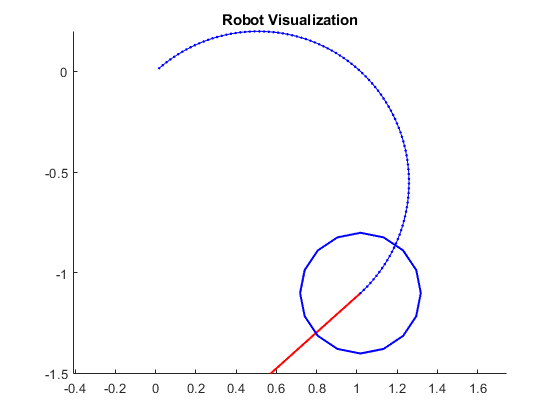

currentPose = initPose;

for idx = 2:numel(tVec) 
    
    % Convert from robot body to world
    vel =  bodyToWorld(bodyV,currentPose);  
   
    % Perform forward discrete integration step
    currentPose = currentPose + vel * sampleTime; 
      
    % Update visualization
    viz(currentPose);

    %Wait for visualization rate
    waitfor(r);
    
end